x =          0    0.0120    0.0240    0.0360    0.0480    0.0601    0.0721    0.0841    0.0961    0.1081    0.1201    0.1321    0.1441    0.1562    0.1682    0.1802    0.1922    0.2042    0.2162    0.2282    0.2402    0.2523    0.2643    0.2763    0.2883    0.3003    0.3123    0.3243    0.3363    0.3483    0.3604    0.3724    0.3844    0.3964    0.4084    0.4204    0.4324    0.4444    0.4565    0.4685    0.4805    0.4925    0.5045    0.5165    0.5285    0.5405    0.5526    0.5646    0.5766    0.5886


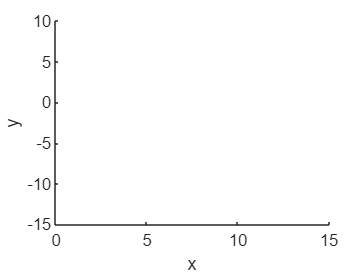

Error using sym/solve>getEqns (line 418)
List of equations must not be empty.

Error in sym/solve (line 226)
[eqns,vars,options] = getEqns(varargin{:});

for m = 0 : 4*pi
x = linspace(m, 4*pi, 1000)
syms sx;
f = 'x.*sin(x) - cos(x)';
sf = x.*sin(x) - cos(x) == 0;
hold on;
plot(x, eval(f))
plot(x, x*0);
xlabel('x'); ylabel('y');
z = [x, 0];
zr = solve(f, sx);
plot(zr, fr ,'r*', z(1), z(2), 'g*');
end